# Código 1 - Walking Robot with simout (e com joelhos a dobrar)

%% Clear everything
clc
clear
close all

Loading simout.mat:

load('simout.mat')

Error using load
'simout.mat' is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\biade\Downloads

Change the MATLAB current folder or add its folder to the MATLAB path.

## Guardar ângulos e tempo em variáveis

- **Perna Esquerda**

time_L =  simout{3}.Values.anklepitch_angle.time;

Undefined variable 'simout'.

Lankle_all = rad2deg(simout{3}.Values.anklepitch_angle.Data);
Lknee_all = rad2deg(simout{3}.Values.knee_angle.Data);
Lhip_all = rad2deg(simout{3}.Values.hippitch_angle.Data);

sz = size(Lankle_all)
tam = sz(1)

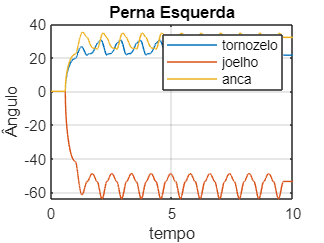


%plot das variáveis conjuntas
plot(time_L, Lankle_all);
hold on 
plot(time_L, Lknee_all);
hold on
plot(time_L, Lhip_all);
hold off

grid on
title('Perna Esquerda');
legend('tornozelo','joelho','anca');
xlabel('tempo');
ylabel('Ângulo');

- **Perna Direita**

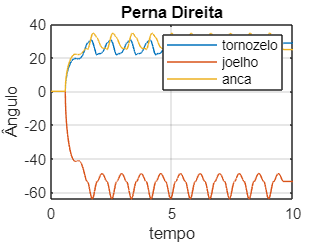

time_R =  simout{2}.Values.anklepitch_angle.time;
Rankle_all = rad2deg(simout{2}.Values.anklepitch_angle.Data);
Rknee_all = rad2deg(simout{2}.Values.knee_angle.Data);
Rhip_all = rad2deg(simout{2}.Values.hippitch_angle.Data);


%plot das variáveis conjuntas
plot(time_R, Rankle_all);
hold on 
plot(time_R, Rknee_all);
hold on
plot(time_R, Rhip_all);
hold off

grid on
title('Perna Direita');
legend('tornozelo','joelho','anca');
xlabel('tempo');
ylabel('Ângulo');

    Vamos então definir os picos de um dos gráficos para conseguirmos limitar os valores a apenas um período. Depois de ter os picos, escolhemos 2 deles.

    Vamos usar a perna direita.

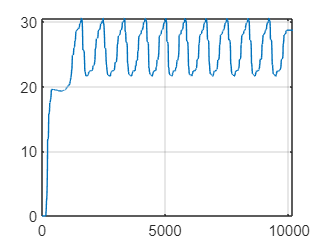

plot(Rankle_all);
xlim([0 tam])
grid on

    Para obter os picos, recorremos à função `findpeaks`. Esta função retorna um vetor composto de dois vetores, onde o primeiro é composto pelos valores dos picos e o segundo pelos respetivos índices desses picos. 

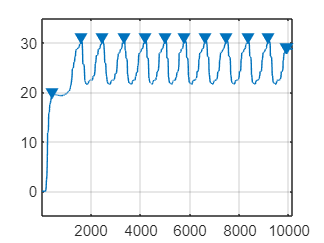

findpeaks(Rankle_all)

[pic,ind] = findpeaks(Rankle_all)

pic =    19.5442
   30.6053
   30.6049
   30.6049
   30.6050
   30.6049
   30.6052
   30.6049
   30.6046
   30.6052


ind =          407
        1604
        2470
        3341
        4183
        5003
        5788
        6633
        7483
        8341


    Escolhendo agora dois picos, obtemos os respetivos índices e tempos.

p1=ind(3)

p1 = 2470

p2=ind(7)

p2 = 5788


t1=time_R(p1)

t1 = 2.4629

t2=time_R(p2)

t2 = 5.7033

    Com todos estes valores, vamos agora definir entao este novo intervalo:

Rankle = Rankle_all(p1:p2);
Rknee = Rknee_all(p1:p2);
Rhip = Rhip_all(p1:p2);
newtime_R = time_R(p1:p2);

Lankle = Lankle_all(p1:p2);
Lknee = Lknee_all(p1:p2);
Lhip = Lhip_all(p1:p2);
newtime_L = time_L(p1:p2);

Fazendo de novo o plot destes novos intervalos:

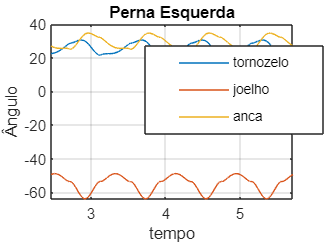

%plot das variáveis conjuntas
plot(newtime_L, Lankle);
hold on 
plot(newtime_L, Lknee);
hold on
plot(newtime_L, Lhip);
hold off

grid on
xlim([t1 t2])
title('Perna Esquerda');
legend('tornozelo','joelho','anca');
xlabel('tempo');
ylabel('Ângulo');

legend('Position',[0.5968,0.54774,0.25505,0.16846])

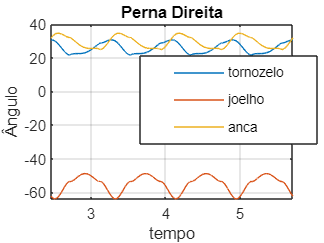

%plot das variáveis conjuntas
plot(newtime_R, Rankle);
hold on 
plot(newtime_R, Rknee);
hold on
plot(newtime_R, Rhip);
hold off

grid on
xlim([t1 t2])
legend('Position',[0.57862,0.50733,0.25505,0.16846])
title('Perna Direita');
legend('tornozelo','joelho','anca');
xlabel('tempo');
ylabel('Ângulo');

Depois de feito o tratamento dos dados necessários, procede-se à `configuração` que permitirá a coneção ao robot e a geração do movimento neste.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%% criação do objeto arduino
clear emanuela; % Limpar a variável do arduino
emanuela = arduino("COM10", "Uno", "BaudRate", 9600);


% Criar um objecto dos servos e conecta-os ao pino correspondente:

clear lk lh la rk rh ra; % limpa as variáveis dos servos

% pins ligados ao lado esquerdo:
lk = servo(emanuela,'D12'); % -> joelho
lh = servo(emanuela,'D9');  % -> anca
la = servo(emanuela,'D10');  % -> pé/tornozelo

% pins ligados ao lado direito:
rk = servo(emanuela,'D8');  % -> joelho
rh = servo(emanuela,'D7');  % -> anca
ra = servo(emanuela,'D2');  % -> pé/tornozelo

%% Define os valores de offset dos servos (obtidos por tentativa e erro)
RhipOffset = 37/180;
RkneeOffset = 94/180;
RankleOffset = 77/180;
LhipOffset = 40/180;
LkneeOffset = 99/180;
LankleOffset = 136/180; %%%ESTE SERVO NAO ESTÁ A FUNCIONAR

%% Estica as pernas
writePosition(lh, LhipOffset);
writePosition(rh, RhipOffset);
writePosition(ra, RankleOffset);
writePosition(la, LankleOffset);
writePosition(lk, LkneeOffset);
writePosition(rk, RkneeOffset);

pause(1); % Pausa de 1 seg

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



## Loop que permite ao robot executar uma marcha contínua

j=10
while(j)
    %75 funcionou
    for i = 1:50:((p2-p1+1))
        walking(lh, LhipOffset + Lhip(i)/180);
        walking(rh, RhipOffset - Rhip(i)/180);
        walking(ra, RankleOffset + Rankle(i)/180);
        walking(la, LankleOffset - Lankle(i)/180);
        walking(lk, LkneeOffset - Lknee(i)/180);
        walking(rk, RkneeOffset + Rknee(i)/180);
        j=j-1;
%         pause(0.01);
    end
end


%Função para se abaixar
x=0;
while(x<25)
        walking(lh, LhipOffset-(x+1)/180);
        walking(rh, RhipOffset-(x-1)/180);
        walking(la, LankleOffset+x/180);
        walking(ra, RankleOffset+x/180);
        walking(lk, LkneeOffset-2*x/180);
        walking(rk, RkneeOffset-2*x/180);
        x = x + 1;
end
pause(5);
x = x - 1;
while(x>=0)
        walking(lh, LhipOffset-(x+2)/180);
        walking(rh, RhipOffset-(x+2)/180);
        walking(la, LankleOffset+x/180);
        walking(ra, RankleOffset+x/180);
        walking(lk, LkneeOffset-2*x/180);
        walking(rk, RkneeOffset-2*x/180);
        x=x-1;
end
pause(10);
x=0

x = 0

while(x<25)
        walking(lh, LhipOffset+(x+1)/180);
        walking(rh, RhipOffset+(x-1)/180);
        walking(la, LankleOffset-x/180);
        walking(ra, RankleOffset-x/180);
        walking(lk, LkneeOffset+2*x/180);
        walking(rk, RkneeOffset+2*x/180);
        x = x + 1;
end
pause(10);
x = x - 1;
while(x>=0)
        walking(lh, LhipOffset+(x+1)/180);
        walking(rh, RhipOffset+(x+1)/180);
        walking(la, LankleOffset-x/180);
        walking(ra, RankleOffset-x/180);
        walking(lk, LkneeOffset+2*x/180);
        walking(rk, RkneeOffset+2*x/180);
        x=x-1;
end

% Função que dado um servo e um ângulo coloca o servo na posição pretendida

function walking(motor, ang)
     if ang>0
        writePosition(motor, ang);
     else
        writePosition(motor, 0); % Não permite que o ângulo ultrapasse o limite
     end
end